# face detection

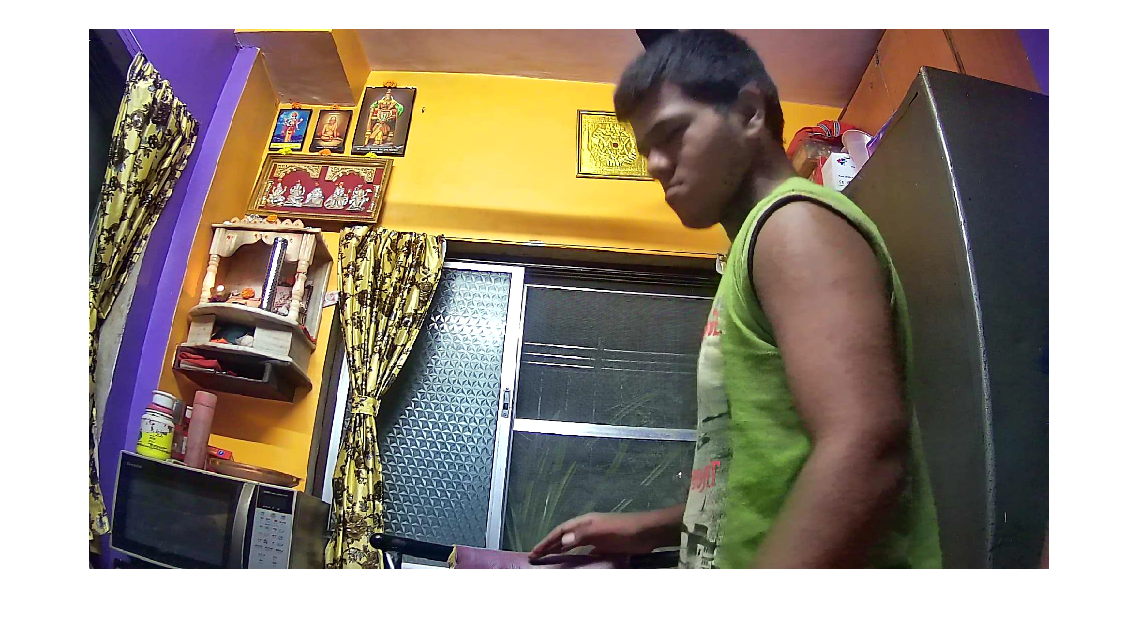

web=webcam('FINGERS 1080 Hi-Res');
im=snapshot(web);
dete=vision.CascadeObjectDetector();
imshow(im);



while true
    im=snapshot(web);
    im2=rgb2gray(im);
    bbox=step(dete,im2);
    pic=insertObjectAnnotation(im,'rectangle',bbox,'face');
    imshow(pic);
end
